# Control MRAC de aeronave JAXA Mu-pal en el eje longitudinal

Sebastian Cubides Toscano

Nicolas Gil Rojas 

Luis Felipe Dávila Goyeneche

clear
close all
A = [-0.0175 0.173 -9.77 -5.63;
     -0.192 -1.09 -0.846 64.6;
     0 0 0 1;
     0.0081 -0.0738 0.0062 -1.9];
B = [-0.428;4.91;0;4.22];

Se desea seguir la respuesta de un modelo de referencia dado por el modelo lineal del eje longitudinal del aeronave JAXA Mu-pal. 

Am = [-0.03 0.166 125.6 37.29;
      -0.052 -1.02 -1554.7 -427.82;
       0 0 0 1;
      0.128 -0.0142 -1335.49 -425.12];
Bm = [-138.1; 1584.2; 0; 1361.6 ];

PLANTA = ss(A,B, eye(4), 0);
MODELR = ss(Am,Bm,eye(4),0);

## RESPUESTA AL PASO DE LA PLANTA

La matriz de estados A y la matriz de la enrada B de la planta linealizada para el eje longitudinal son las que se muestran a continuación.

                                                   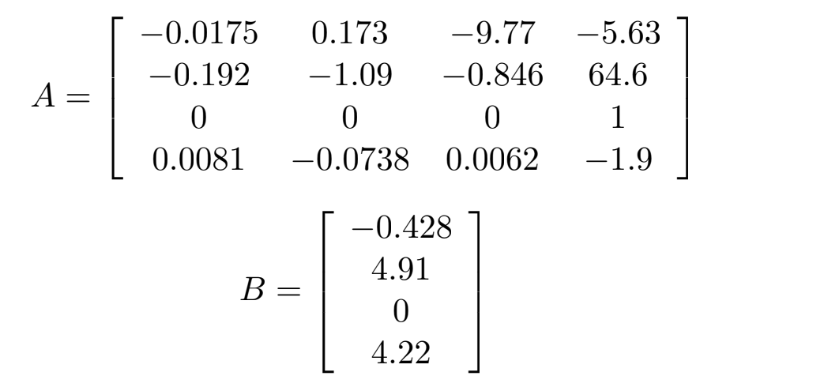

En el siguiente  gráfico se muestra la respuesta al paso de los 4 estados del sistema, donde el primer estado corresponde con la velocidad en x $u_x$, el segundo estado es la velocidad en z $u_z$, el tercer estado al ángulo de pitch $\theta
$ y el cuarto estado es la velocidad angular de pitch $q
$. 

Ante una entrada paso de magnitud 1 la velocidad en x se tiene a un valor por debajo de -200 $\frac{m}{s^2}$, la velocidad en z 36 $\frac{m}{s^2}$, el ángulo de pitch a 1 $rad
$  y la velocidad de pitch a cero. 

La respuesta en todos los estado es subamortiguada pero asintoticamente estable por tanto se espera que la planta sea estable y controlable. 

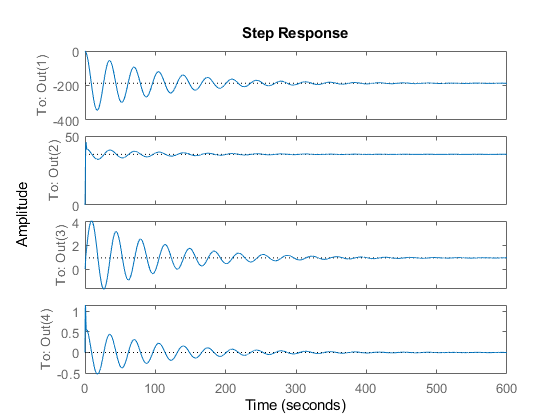

step(PLANTA)

Para verificar los supuestos se hallan los valores propios de A y se determina el rango de la matriz de controlabilidad del sistema. 

Los autovalores de A se encuentran todos en el semiplano izquierdo por tanto A es estable. 

                                          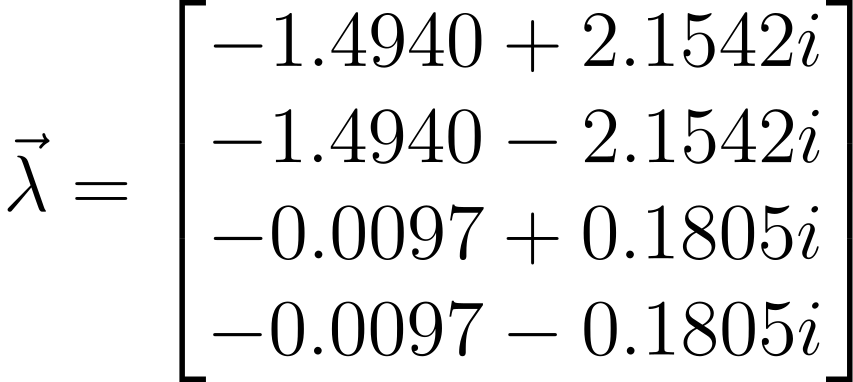

La matriz de controlabilidad es la siguiente:

            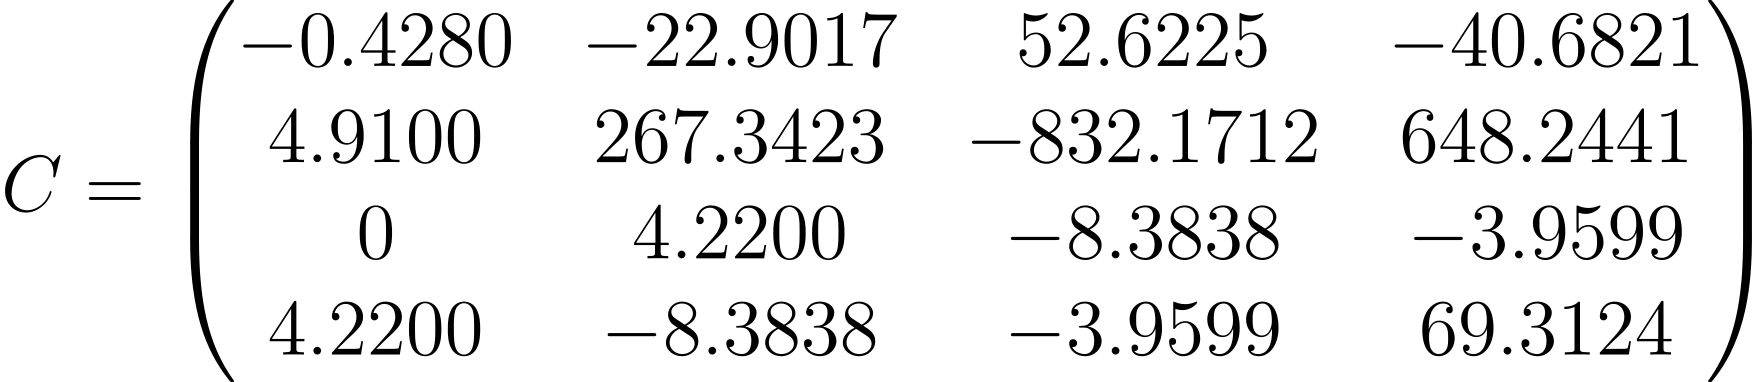

El rango de esta matriz es 4 por lo tanto es completo por columnas y filas y entonces el sistema es controlable.

## RESPUESTA AL PASO MODELO DE REFERENCIA

El modelo de referencia que se quiere seguir está representado por las siguientes matrices $A_m
$ y $B_m
$

             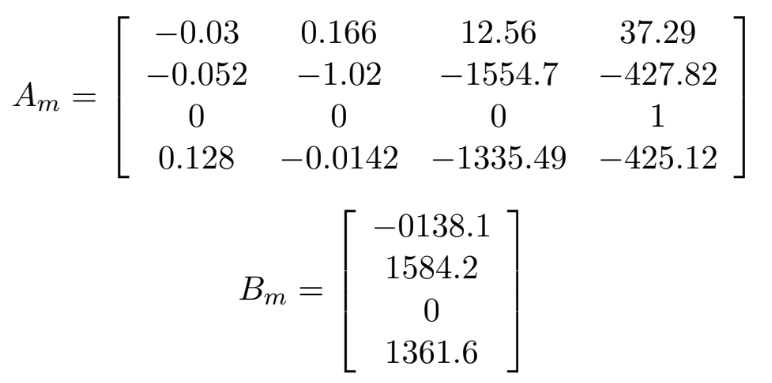

La respuesta al paso del sistema de referencia muestra los mismo punto de estado estacionario para los 4 estados. En particular las velocidades en x y z llega estado estacionario en -200 $\frac{m}{s^2}$ y 39.1 $\frac{m}{s^2}$ respectivamente. 

Si bien la diferencia en los puntos de estado estable no es significativa, este modelo de referencia cumple con el objetivo de amortiguar criticamente la respuesta en tiempo. De este modo, el objetivo de control en este caso es seguir el sistema de referencia para que la respuesta al paso sea criticamente amortiguada según los criterios de obtención del modelo de referencia. 

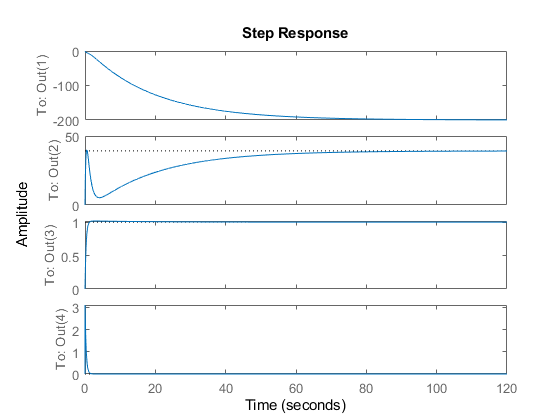

step(MODELR)

## GANANCIAS DE CONTROL

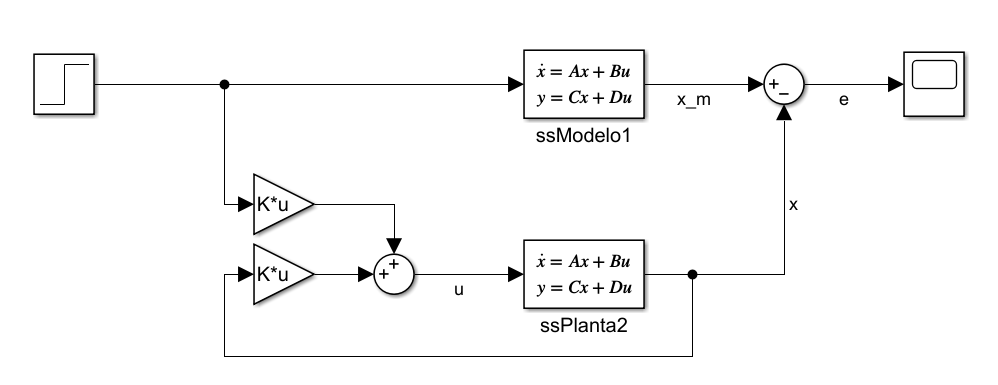

La ley de control que se propone en el control adaptativo con sistema de referencia  supone que es posible hallar ganancias Kx y Kr adecuadas que ubican los valores propios y la ganancia de A+BKx identicamente a los valores propios y ganacia de Am y que Bm sea identica a  BKr donde:

                                                           
$$u = K_xx + K_r r$$


Si estas ganancias existen entonces el sistema en lazo cerrado que se muestra arriba tiene error de estado estable cero y los estados $x$ siguen a los estados $x_m$.

Estas ganancias puede ser determinadas con el método de la pseudo-inversa, que perimite hallar soluciones de error cudratico mínimo. Tenemos entonces que:

                                                    
$$A_m = A + BK_x\\
A_m-A=BK_x\\
B^T(A_m-A)=B^TBK_x\\
K_x = (B^TB)^{-1}B^T(A_m-A)$$


 Con un procedimiento similar se encuentra que:

                                                    
$$K_r = (B^TB)^{-1}B^TB_m$$


De acuerdo con las expresiones anteriores obtenemos aproximaciones para las ganacias ideales.

                            

                           

Kx = inv(B'*B)*B'*(Am - A);

Kx =     0.0285    0.0142 -316.4669 -100.2891


Kr = inv(B'*B)*B'*Bm;

Kr = 322.6504

Para verificar hallamos la norma de los errores $A_m - A-BK_x$ y $B_m-BK_r$. La norma usada en este caso se define como: $||A||^2_F =trace(A^TA)$.

$||A_m - A-BK_x||_F^2$ =  0.0061

$||B_m-BK_r||^2_F$= 4.474e-4

Adicionalmente, se halla la respuesta al paso del sistema $A+BK_x$ y $BK_r$ para los 4 estados. 

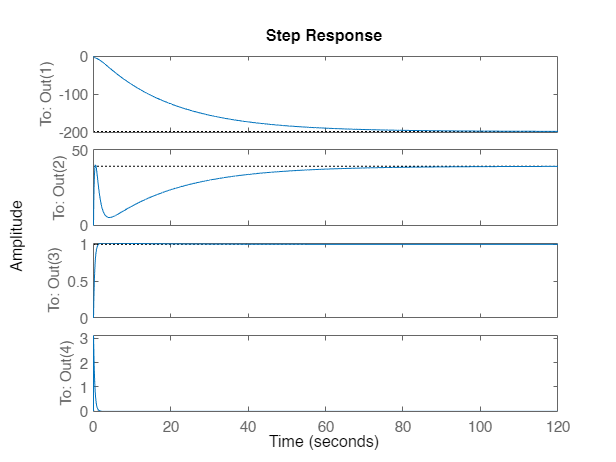

Eam = Am - A - B*Kx;
Ebm = Bm- B*Kr;
trace(Eam'*Eam);
trace(Ebm'*Ebm);
step(ss(A+B*Kx, B*Kr, eye(4),0))

Al comparar el error de posición entre este sistema y el sistema de referencia, se econtró que el error en estado estable es:

                                                    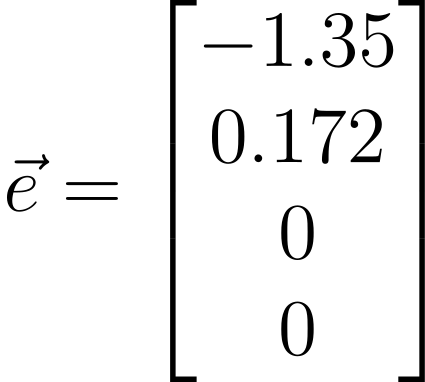

Para estas ganancias se logra error de estado estable cero para el ángulo de pitch.

## LEY DE ADAPTACIÓN

Sea el sistema a controlar $\dot{x} = Ax + B\Lambda u$ y el sistema de referencia $\dot{x}_m =A_mx_m+B_mr$ se propone la señal de control $u = K_xx+K_rr$ donde:


$$A_m = A + B\Lambda K_x$$



$$B_m = B\Lambda K_r$$


Sean $\hat K_x $ y $\hat K_r$ estimadores de las ganacias $K_x$ y $K_r$ respectivamente, el error de seguimiento del sistema de control adaptativo queda definido como:


$$\dot{e} = A_me-B\Lambda \tilde K_xx- B\Lambda \tilde K_rr$$



$$\tilde K_{x,r} = \hat K_{x,r} - K_{x,r}$$


Se propone la función de lypunov candidata:


$$V = trace(Pee^T) + ||B\Lambda \tilde K_x \lambda_x||^2_F+ ||B\Lambda \tilde K_r\lambda_r||^2_F$$



$$V = trace(Pee^T) + trace((B\Lambda \tilde K_x \lambda_x)^T(B\Lambda \tilde K_x \lambda_x))+trace((B\Lambda \tilde K_r\lambda_r)^T(B\Lambda \tilde K_r\lambda_r))$$



$$\dot{V} = tr((A_m^TP+PA_m)ee^T) -2tr(xe^TPB\Lambda \tilde K_x + re^TPB\Lambda \tilde K_r) + 2tr(\dot{\tilde K_x}^T M \tilde K_x\Gamma_x + \dot{\tilde K_r}^T M \tilde K_r\Gamma_r)$$


Definiendo las siguientes matrices como:

$Q = -(A_m^TP+PA_m)$ ,  $\Gamma_{x,r} =   \lambda_{x,r}^T \lambda_{x,r} =  \lambda_{x,r}\lambda_{x,r}^T $ con $Q$ definida positiva $P$ y $\Gamma$ simétricas y positivas. $M = (B\Lambda)^T(B\Lambda)$


$$\dot{\tilde K_x}^T = \Gamma_x^{-1} xe^TPB\Lambda M^{-1}$$



$$\hat \dot{K}_x = \dot{\tilde K_x} = M^{-1}(B\Lambda)^TPex^T\Gamma_x^{-1}$$



$$\dot{\tilde K_r}^T = \Gamma_r^{-1} re^TPB\Lambda M^{-1}$$



$$\hat \dot{K}_r = \dot{\tilde K_r} = M^{-1}(B\Lambda)^TPer^T\Gamma_r^{-1}$$


Se demuestra que $\dot V$ es definida negativa y V decae a cero asintoticamente.

$\dot{V} = tr(-Qee^T)  = -e^TQe$ < $||Q||^2_{\infty}||e||^2=-\lambda(Q)||e||^2$

La ley de adaptación es entonces:


$$\hat \dot{K}_x =M^{-1}(B\Lambda)^TPex^T\Gamma_x^{-1}$$



$$\hat \dot{K}_r  = M^{-1}(B\Lambda)^TPer^T\Gamma_r^{-1}$$


Utilizando la siguiente propiedad:

                                       
$$vec(AXB) = (A\otimes B^T)vec(X)$$


la ley de control se reescribe como sigue:

                                        
$$vec(\hat \dot{K}_x) =(M^{-1}(B\Lambda)^TP\otimes \Gamma_x^{-1})vec(ex^T)$$


                                       
$$vec(\hat \dot{K}_r) =(M^{-1}(B\Lambda)^TP\otimes \Gamma_r^{-1})vec(er^T)$$


$vec(V)$ apila las filas de la matriz en un vector de nxn componentes y $\otimes$ es un producto tensor que en matlab se calcula con la función kron(). Para el sistema tratado en esta tarea las matrices $(M^{-1}(B\Lambda)^TP\otimes \Gamma_x^{-1})$ y $(M^{-1}(B\Lambda)^TP\otimes \Gamma_r^{-1})$ son de tamaño 4x16 y 1x4 respectivamente. Además, $vec(ex^T) $ y $vec(er^T) $son vectores de 16 y 4 componentes, donde cada una de estas son los productos cruzados del error con cada uno de los estados del sistema y la referencia. 

## SELECCIÓN DE LAS MATRICES DE PONDERACIÓN.

La matriz $\Lambda$ en este caso es un escalar y se toma como 1. La matriz P se halla con la solución de la ecuación de Lyapunov para un $Q = 2I$, este valor para Q se halla ieterando hasta logra que la energía del sistema fuese lo más parecida a la energía del sistema con las ganacias halladas por pseudo inversa. $\Gamma_x = 0.6I$ y $\Gamma_r = 0.4I$ estas tambien se seleccionaron con el criterio de la energía. En una primera aprocximación se tomaron altos valores para estas matrices logrando seguimiento criticamente amortiguado, sin embargo la energía era del orden de 10e+6 y se fueron bajando estos valores hasta que la respuesta ante una saturación de [-100,100] se hiciera seguimiento con error de posición cercano a cero. 

V = 1;
MBV = inv(B'*B)*B';
P = lyap(Am, eye(4)*2);
Gamax = eye(4)*0.5;
Gamar = eye(1)*0.3;
Z = kron(MBV*P,inv(Gamax)');
Z';
Zr =kron(MBV*P,inv(Gamar)');

## SIMULACIÓN MRAC

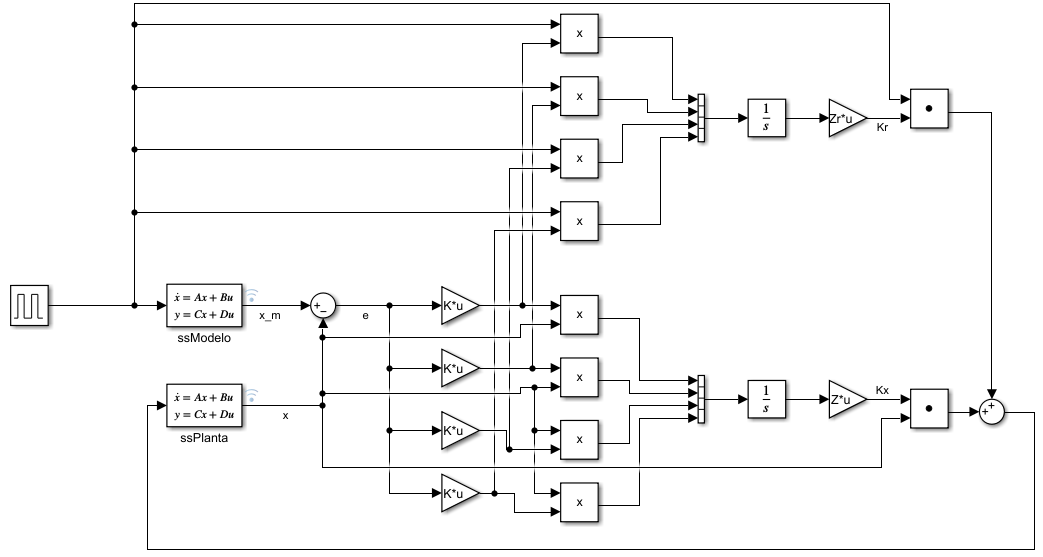

## MATRICES DE ADAPTACIÓN FINALES

Las matrices de adaptación en estado estable que se lograron son las siguientes.

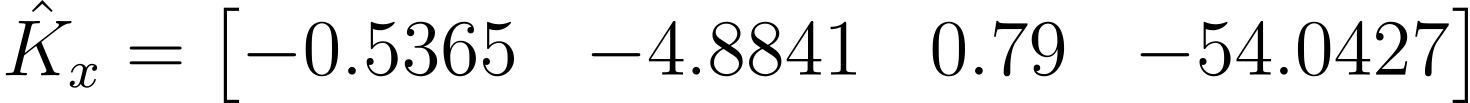

Estas ganancias se alejan de las halladas por la pseudo inversa y además en lazo cerrado no logran llevar a A+BKx y BKr a Am y Bm. Pero el seguimiento que se logra tiene error de posición en pitch de 0.005 rad y en la velocidad en x de -0.5 m/s2. El siguiente gráfico muestra la respuesta del sistema con las ganancias finales. 

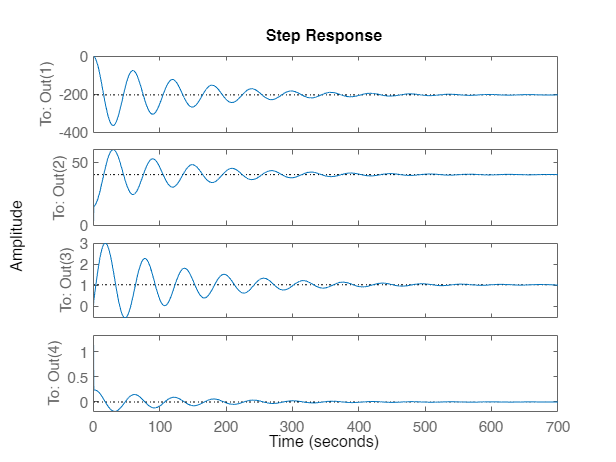

Krf = 86.5;
Kxf = [-0.5365 -4.8841 0.79 -54.0427];
Eamf = Am - A - B*Kxf;
Ebmf = Bm- B*Krf;
trace(Eamf'*Eamf);
trace(Ebmf'*Ebmf);
A+B*Kxf;
B*Krf;
step(ss(A+B*Kxf,B*Krf,eye(4),0))

### Seguimiento ante una referencia paso sin saturación.

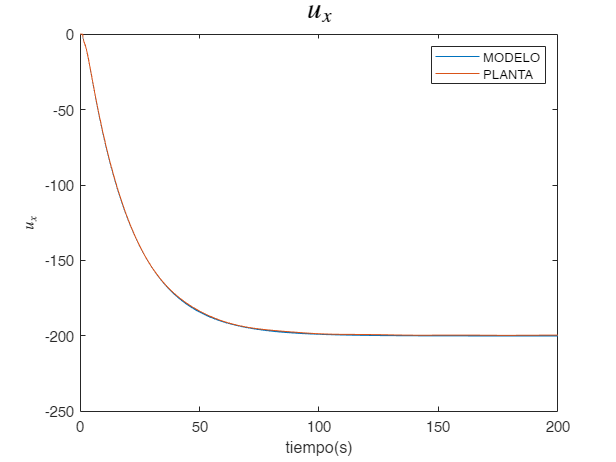

plot(x1m);hold on,plot(x1p);


% Create ylabel
ylabel('$u_x$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$u_x$','FontSize',20,'Interpreter','latex');

xlim([0 200])
ylim([-250 0])
legend({'MODELO','PLANTA'})
hold off

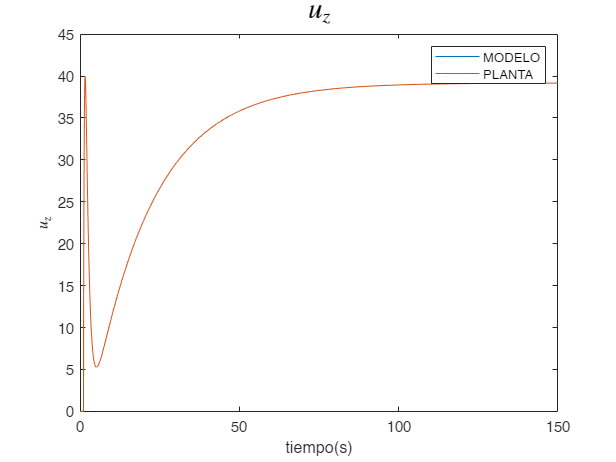

plot(x2m);hold on,plot(x2p);

% Create ylabel
ylabel('$u_z$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$u_z$','FontSize',20,'Interpreter','latex');

legend({'MODELO','PLANTA'})

xlim([0 150])
ylim([0.0 45.0])
hold off

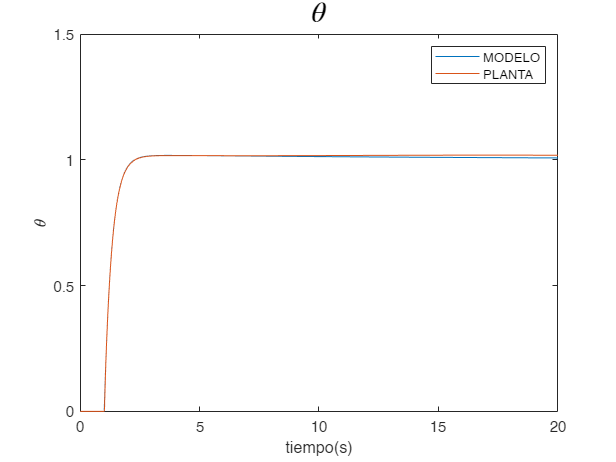

plot(x3m);hold on,plot(x3p);

% Create ylabel
ylabel('$\theta$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$\theta$','FontSize',20,'Interpreter','latex');

legend({'MODELO','PLANTA'})

xlim([0 20])
ylim([0.0 1.5])
hold off

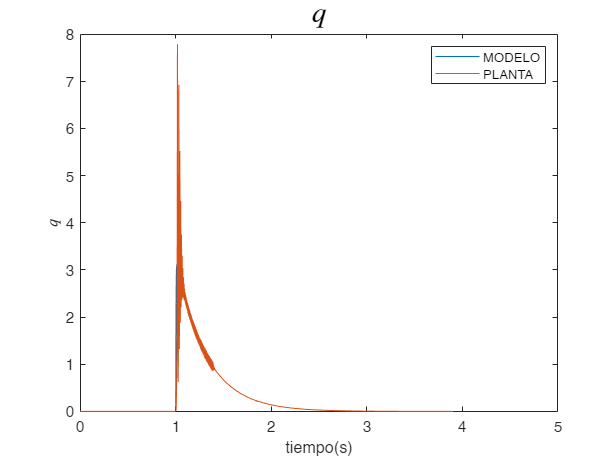

plot(x4m);hold on,plot(x4p);

% Create ylabel
ylabel('$q$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$q$','FontSize',20,'Interpreter','latex');

legend({'MODELO','PLANTA'})

xlim([0 5])
ylim([0.0 8])
hold off

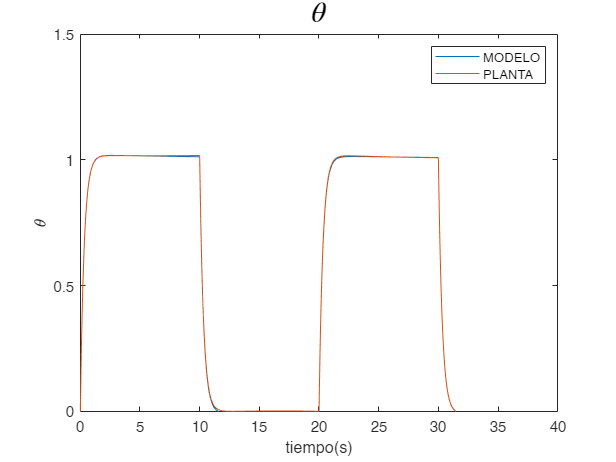

plot(x3mpulsos);hold on,plot(x3ppulsos);

% Create ylabel
ylabel('$\theta$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$\theta$','FontSize',20,'Interpreter','latex');

legend({'MODELO','PLANTA'})

xlim([0 40])
ylim([0.0 1.5])
hold off

Sin la saturación el MRAC implementado sigue las referencias de tipo paso y además logra seguir trenes de pulsos de más de 5 segundos de periodo. El máximo error para el pitch es de 0.005 rad 

### Seguimiento ante referencia paso con saturación

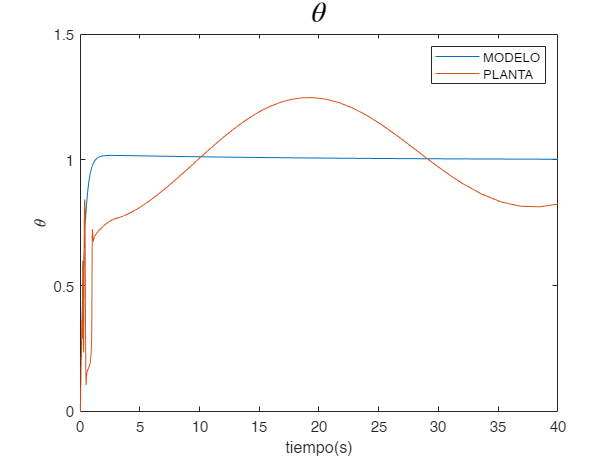

plot(SATr);hold on,plot(SAT);

% Create ylabel
ylabel('$\theta$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$\theta$','FontSize',20,'Interpreter','latex');

legend({'MODELO','PLANTA'})

xlim([0 40])
ylim([0.0 1.5])
hold off

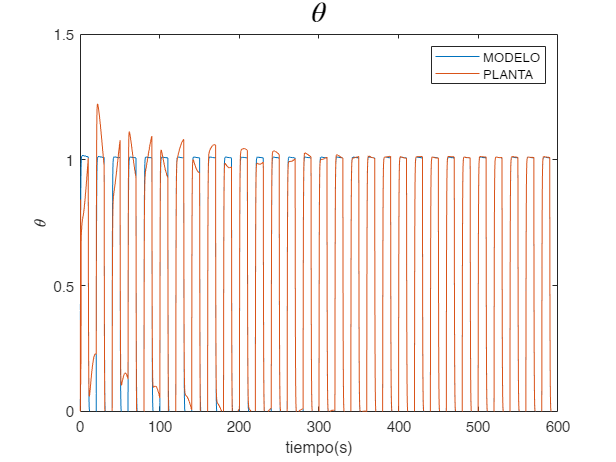

plot(SATP);hold on,plot(SATP2);

% Create ylabel
ylabel('$\theta$','Interpreter','latex');

% Create xlabel
xlabel({'tiempo(s)',''});

% Create title
title('$\theta$','FontSize',20,'Interpreter','latex');

legend({'MODELO','PLANTA'})

xlim([0 600])
ylim([0.0 1.5])
hold off

En presencia de saturación el MRAC se adapta lentamente, vemos que tiene un tiempo de establecimiento de más de 250 segundos a partir de ahí se logra adaptar y alcanza a seguir la referencia de tipo tren de pulsos pasasdos los 300 segundos. Cuando ya se ha adaptado, el error de segumiento máximo vuelve a ser de 0.005 rad